clc
clear

Kt = 0.011;
Km = 327*10^-6;
M = 1.513;
Ixx = 0.0185;
Iyy = 0.0201;
Izz = 0.0286;
g = 9.82;
lroll = 0.175;
lpitch = 0.175;
omega_m = 0;%M*g/(4*Kt);

n = 12; % number of states
m = 4; % number of inputs
p = 12; % number of outputs

Hp = 2; % prediction horizon
Hu = 1; % control horizon
Q = zeros(Hp*p); % error weight
%Q(10,10) = 100;
%Q(11,11) = 100;
%Q(12,12) = 100;
%Q(22,22) = 100;
%Q(23,23) = 100;
%Q(24,24) = 100;
Q(9,9) = 100;
Q(21,21) = 100;

R = 0.001*eye(Hu*m); % change in actuation weight

Tau = zeros(n*Hp,1); % reference tau

## Linear model and lifting

A = [zeros(6,6)  [0 0 0 0 -g 0; 0 0 0 g 0 0 ; zeros(4,6)];
    eye(6) zeros(6,6)];
B = [zeros(4,2) [Kt/M -(lroll*Kt)/(Ixx) -(lpitch*Kt)/(Iyy) (Km)/(Izz); 
    Kt/M (lroll*Kt)/(Ixx) (lpitch*Kt)/(Iyy) (Km)/(Izz); 
    Kt/M (lroll*Kt)/(Ixx) -(lpitch*Kt)/(Iyy) -(Km)/(Izz); 
    Kt/M -(lroll*Kt)/(Ixx) (lpitch*Kt)/(Iyy) -(Km)/(Izz)] zeros(4,6)].';
%C = [zeros(6) eye(6)];
C = eye(p,n);
D = zeros(p,m);

SSModel = ss(A,B,C,D);
opt = c2dOptions('Method','tustin');
sys = c2d(SSModel,1,opt);

% Lift matrices
[ALift, BuLift, BduLift, Psi, Upsilon, Theta] = MPCLift(sys.A, sys.B, sys.C, Hp, Hu);

Condition of:
 Psi: 848.799516
 Upsilon: 146.140442 
 Theta: 146.140442

simTime = 100;
t = 0:1:simTime - 1;

x = zeros(n,simTime);
u = zeros(m,simTime);
uopt = zeros(m,simTime);
du = zeros(m,simTime);
slackplot = zeros(8,simTime);

x(:,1) = zeros(n,1);
%u(:,1) = zeros(m,1);
u(:,1) = omega_m;
%x(9,1) = 1;

Tau(9,1) = 0.1;
%Tau(8,1) = 10;
Tau(21,1) = 0.1;
%Tau(20,1) = 10;

for i=2:simTime
    yalmip('clear')
    duopt = sdpvar(Hu*m,1);
    slack = sdpvar(4,1);
    %constraint = [10 0 0 0;0 10 0 0; 0 0 10 0; 0 0 0 10;-10 0 0 0;0 -10 0 0; 0 0 -10 0; 0 0 0 -10]*duopt <= -eye(8,1);

    % Calculate the Plant
    x(:,i) = sys.A*x(:,i-1) + sys.B*(u(:,i-1));

    uopt(:,i-1) = u(:,i-1) - omega_m;

    Epsilon = Tau - Psi * x(:,i) - Upsilon * uopt(:,i-1);
    G = 2 * Theta.' * Q * Epsilon;
    H = Theta.' * Q * Theta + R;
    objective = (duopt.' * H * duopt - duopt.' * G);
    %constraint = [[0.5 0 0 0;0 0.5 0 0; 0 0 0.5 0; 0 0 0 0.5]*duopt<=eye(4,1)+slack];
    constraint = [2*duopt <= 1 ; -1 <= 2*duopt];

    ops = sdpsettings('solver','ipopt');
    ops.verbose = 0; % makes yalmip quiet
    optimize(constraint,objective, ops);

    %    cvx_begin quiet
    %    variable duopt(Hu*m)
    %    Epsilon = Tau - Psi * x(:,i) - Upsilon * uopt(:,i-1);
    %    minimize (Theta * duopt - Epsilon)' * Q * (Theta * duopt - Epsilon) + duopt' * R * duopt
    %    subject to
    %        [10 0 0 0;0 10 0 0; 0 0 10 0; 0 0 0 10;-10 0 0 0;0 -10 0 0; 0 0 -10 0; 0 0 0 -10]*duopt <= -eye(8,1)
    %cvx_end 

    du(:,i) = duopt(1:4,1);
    slackplot(1:4,i) = slack;

    u(:,i) = u(:,i-1) + du(:,i);
end


******************************************************************************
This program contains Ipopt, a library for large-scale nonlinear optimization.
 Ipopt is released as open source code under the Eclipse Public License (EPL).
         For more information visit http://projects.coin-or.org/Ipopt
******************************************************************************



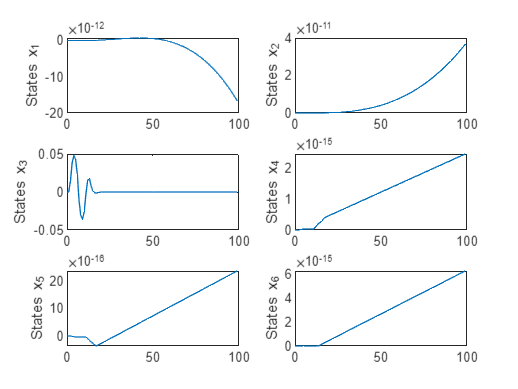

figure(1);
subplot(3,2,1)
plot(t, x(1,:));
ylabel("States x_1")
subplot(3,2,2)
plot(t, x(2,:));
ylabel("States x_2")
subplot(3,2,3)
plot(t, x(3,:));
ylabel("States x_3")
subplot(3,2,4)
plot(t, x(4,:));
ylabel("States x_4")
subplot(3,2,5)
plot(t, x(5,:));
ylabel("States x_5")
subplot(3,2,6)
plot(t, x(6,:));
ylabel("States x_6")

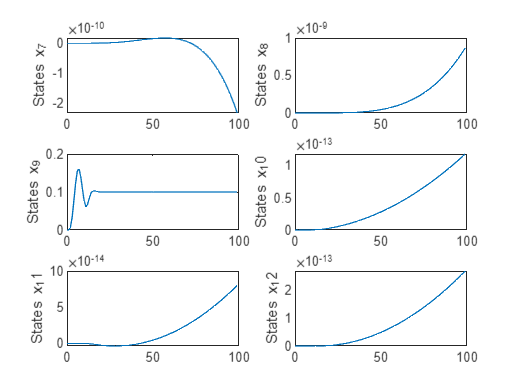

figure(2);
subplot(3,2,1)
plot(t, x(7,:));
ylabel("States x_7")
subplot(3,2,2)
plot(t, x(8,:));
ylabel("States x_8")
subplot(3,2,3)
plot(t, x(9,:));
ylabel("States x_9")
subplot(3,2,4)
plot(t, x(10,:));
ylabel("States x_10")
subplot(3,2,5)
plot(t, x(11,:));
ylabel("States x_11")
subplot(3,2,6)
plot(t, x(12,:));
ylabel("States x_12")

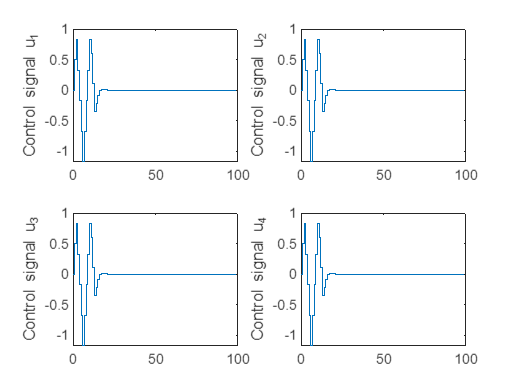

figure(3)
subplot(2,2,1)
stairs(t, u(1,:));
ylabel("Control signal u_1")
subplot(2,2,2)
stairs(t, u(2,:));
ylabel("Control signal u_2")
subplot(2,2,3)
stairs(t, u(3,:));
ylabel("Control signal u_3")
subplot(2,2,4)
stairs(t, u(4,:));
ylabel("Control signal u_4")

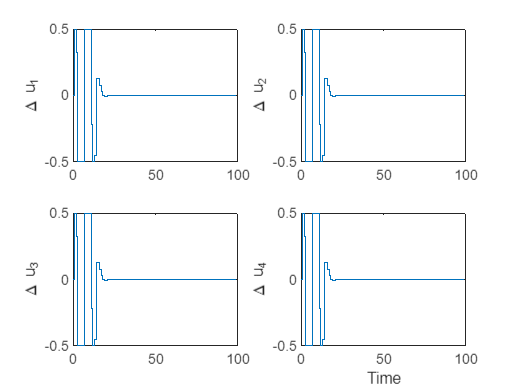

figure(4)
subplot(2,2,1)
stairs(t, du(1,:));
ylabel("\Delta u_1")
subplot(2,2,2)
stairs(t, du(2,:));
ylabel("\Delta u_2")
subplot(2,2,3)
stairs(t, du(3,:));
ylabel("\Delta u_3")
subplot(2,2,4)
stairs(t, du(4,:));
ylabel("\Delta u_4")
xlabel("Time")

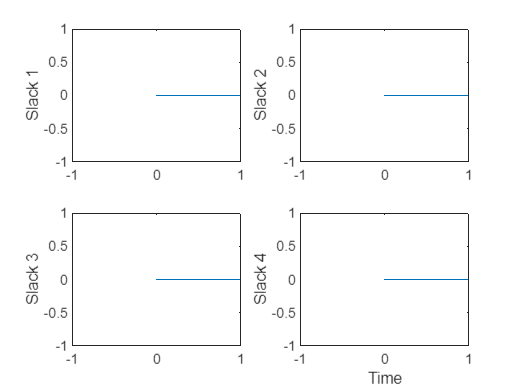

figure(5)
subplot(2,2,1)
stairs(t, slackplot(1,:));
ylabel("Slack 1")
subplot(2,2,2)
stairs(t, slackplot(2,:));
ylabel("Slack 2")
subplot(2,2,3)
stairs(t, slackplot(3,:));
ylabel("Slack 3")
subplot(2,2,4)
stairs(t, slackplot(4,:));
ylabel("Slack 4")
xlabel("Time")

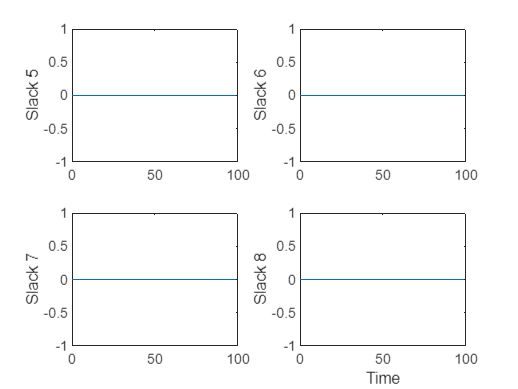

figure(6)
subplot(2,2,1)
stairs(t, slackplot(5,:));
ylabel("Slack 5")
subplot(2,2,2)
stairs(t, slackplot(6,:));
ylabel("Slack 6")
subplot(2,2,3)
stairs(t, slackplot(7,:));
ylabel("Slack 7")
subplot(2,2,4)
stairs(t, slackplot(8,:));
ylabel("Slack 8")
xlabel("Time")

function [ALift, BuLift, BduLift, Psi, Upsilon, Theta] = MPCLift(A, B, C, Hp, Hu)
    n = length(A);
    p = size(B,2);
    ALift = zeros(Hp*n,n);
    BuLift = zeros(Hp*n,p);
    BduLift = zeros(Hp*n,Hu*p);
    for i=1:Hp
        ALift((i-1)*n+1:i*n,:) = A^i;

        Asum = 0;
        for j=2:i
            Asum = Asum + ALift((j-2)*n+1:(j-1)*n,:);
        end
        % We add B, since the above loop doesnt go A^0*B = 1*B = B
        BuLift((i-1)*n+1:i*n,:) = Asum * B + B;
    end

    for i=1:Hu
        BduLift((i-1)*n+1:end,(i-1)*p+1:i*p) = BuLift(1:(Hp-(i-1))*n,:);
    end

    C_vec = kron(eye(Hp), C);
    cal_C = blkdiag(C_vec);
    
    Psi = cal_C * ALift;
    Upsilon = cal_C * BuLift;
    Theta = cal_C * BduLift;
    fprintf("Condition of:\n Psi: %f\n Upsilon: %f \n Theta: %f",cond(Psi),cond(Upsilon),cond(Theta))
    
end